##    **TOP- RECOMMENDATION VIA MATRIX COMPLETION**

DATASETS 

1)Delicious Dataset

% data_path ="C:\Users\Manas\Desktop\MFC FINAL\soc-delicious.mtx";
% disp("Running Delicious dataset...");
% 
% data = importdata(data_path,' ',2);  % skip 2 header lines
% edges   = data.data(:,1:2);
% users   = edges(:,1);
% items   = edges(:,2);
% ratings = ones(size(users));
% 
% R = sparse(users, items, ratings);
% R = R(:, sum(R,1) >= 3);   % keep items with ≥3 users

2)Last.fm Dataset

% 
% clc; clear; close all;
% tic;4
% 
% %% === Step 1: Load user–artist interactions ===
% fname = "C:\Users\Manas\Desktop\MFC-S3\user_artists.dat";
% fprintf('Loading raw user–artist interactions from %s ...\n', fname);
% 
% data = readtable(fname, 'Delimiter', '\t', 'ReadVariableNames', false);
% users = data.Var1;
% artists = data.Var2;
% plays  = data.Var3;
% 
% fprintf('Total interactions: %d\n', height(data));
% 
% %% === Step 2: Build implicit user–artist matrix ===
% R = sparse(users, artists, plays > 0);
% fprintf('Initial matrix: %d users × %d artists (%.4f %% density)\n', ...
%         size(R,1), size(R,2), 100*nnz(R)/numel(R));
% 
% %% === Step 3: Filter users/items with ≥10 interactions ===
% R = R(sum(R,2) >= 5, sum(R,1) >= 5);
% [m,n] = size(R);
% fprintf('Filtered matrix: %d users × %d artists (%.4f %% density)\n', ...
%         m, n, 100*nnz(R)/numel(R));
% 
% %% === Optional smaller subset for quick testing ===
% % R = R(1:1000, 1:4000); [m,n] = size(R);
% 
% %% === Step 4: Train/Test Split ===
% Train = R;
% test = cell(m,1);
% test_zhong = zeros(m,1);
% 
% for i = 1:m
%     idx = find(R(i,:));
%     if numel(idx) >= 2
%         test_item = idx(randi(length(idx))); % (or random: idx(randi(length(idx))))
%         test_zhong(i) = test_item;
%         Train(i,test_item) = 0;
%         test{i} = setdiff(1:n, find(Train(i,:)));
%     else
%         test{i} = [];
%         test_zhong(i) = 0;
%     end
% end
% fprintf('Train/Test split done. %d users have test items.\n', sum(test_zhong>0));
% 
% %% === Step 5: Parameters ===
% fprintf('\n=== Parameter Tuning (LastFM) ===\n');
% bestHR = 0;
% best = [0 0 0];
% 
% for mu = [0.05 0.08 0.1]
%     for rho = [2 3 4]
%         for kappa = [1.0 1.2 1.5]
%             fprintf('\n--- mu=%.3f rho=%.1f kappa=%.1f ---\n', mu, rho, kappa);
%             [hr_temp, arhr_temp, ~] = recom_mc(Train, test, test_zhong, mu, rho, kappa);
%             fprintf('HR@10 = %.4f | ARHR@10 = %.4f\n', hr_temp(2), arhr_temp);
%             if hr_temp(2) > bestHR
%                 bestHR = hr_temp(2);
%                 best = [mu rho kappa];
%             end
%         end
%     end
% end
% toler=1e-6;
% maxiter=300;
% 
% fprintf('\nBest combination: mu=%.3f rho=%.1f kappa=%.1f | HR@10=%.4f\n', ...
%         best(1), best(2), best(3), bestHR);
% 
% 
% %% === Step 6: Run LogDet Matrix Completion ===
% fprintf('\nRunning LogDet Matrix Completion on LastFM data...\n');
% [hr, arhr, X] = recom_mc(Train, test, test_zhong, mu, rho, kappa);
% 
% %% === Step 7: Display Results ===
% fprintf('\n========= RESULTS (LastFM) =========\n');
% fprintf(' HR@5  = %.4f\n', hr(1));
% fprintf(' HR@10 = %.4f\n', hr(2));
% fprintf(' HR@15 = %.4f\n', hr(3));
% fprintf(' HR@20 = %.4f\n', hr(4));
% fprintf(' HR@25 = %.4f\n', hr(5));
% fprintf(' ARHR@10 = %.4f\n', arhr);
% fprintf('====================================\n');
% 
% toc;

3)Book-Crossing(BX)

%  data_path = "C:\Users\Manas\Desktop\MFC FINAL\Ratings.csv\Ratings.csv";
%  disp("Running BX dataset...");
% 
%  T = readtable(data_path,'Delimiter',';');
% % 
%  users   = T.User_ID;
%  isbns   = T.ISBN;
%  ratings = T.Rating; ratings(ratings > 0) = 1;
% % % 
%  [unique_users, ~, user_idx] = unique(users);
%  [unique_books, ~, item_idx] = unique(isbns);
% % 
%  R = sparse(user_idx, item_idx, ratings);
%  R = R(sum(R,2) >= 10, sum(R,1) >= 10);


4)MovieLens 100k

%     data_path = "C:\Users\Manas\Desktop\mfc\ml-100k\ml-100k\u.data";
%  disp("Running MovieLens 100K dataset...");

Running MovieLens 100K dataset...


% % 
%  T = readtable(data_path, 'FileType', 'text', 'Delimiter', '\t', ...
%      'ReadVariableNames', false, 'Format', '%d %d %d %d');
% % 
%  users   = T.Var1;
%  items   = T.Var2;
%  ratings = double(T.Var3)

ratings =      3
     3
     1
     2
     1
     4
     2
     5
     3
     3


% % ;
% % 
%  R = sparse(users, items, ratings);


5) NETFLIX 

% %netflix 
% % %% Netflix Dataset Loader
 % 
% % % Set data path (change this if your dataset is stored somewhere else)
 data_path = "C:\Users\Manas\Desktop\MFC-S3\netmain";
% % 
% % % Full and mini dataset file names
 full_file = fullfile(data_path, "netflix_ratings.csv");       % Original dataset
  mini_file = fullfile(data_path, "netflix_ratings_mini.csv");  % Smaller subset
% % 
% % % Check if mini file exists
  if ~isfile(mini_file)
      fprintf("Mini Netflix file not found. Generating...\n");
% 
% %     % Read full Netflix dataset
      if ~isfile(full_file)
         error("Full Netflix file not found at: %s", full_file);
      end
% % 
      T_full = readtable(full_file);
% 
% %     % Take first 100,000 rows (you can change this number)
      num_rows = min(1000, height(T_full));
      T_mini = T_full(1:num_rows, :);
% % 
% %     % Save mini dataset
      writetable(T_mini, mini_file);
      fprintf("Mini Netflix dataset created: %s\n", mini_file);
  end
% % 
% % %% Load the Mini Netflix Dataset
  fprintf("Loading mini Netflix dataset...\n");

Loading mini Netflix dataset...


  T = readtable(mini_file);
% % 
% % % Extract user, item, rating columns
  users   = T.userId;
  items   = T.movieId;
  ratings = T.rating;
% % % 
%  % Create sparse user-item matrix
  m = max(users);
  n = max(items);
  R = full(sparse(users, items, ratings, m, n));
% % 
  fprintf("Dataset loaded successfully: %d users, %d items, %d ratings.\n", ...
            m, n, nnz(R));

Dataset loaded successfully: 2649426 users, 30 items, 100000 ratings.


function run_recom_mc_report(R)

MU0        = 0.06;       % initial ALM penaltya
GAMMA      = 2.0;        % penalty growth
TOLER      = 1e-6;       % convergence tolerance
MAXITER    = 100;        % was 1500 (reduced for speed)
MU_MAX     = 1e6;        % cap to avoid numerical blowup

NUM_TRIALS = 5;          % number of trials
SEED0      = 42;         % random seed

FULL_EVAL   = false;     % true: rank against all unrated items
NEG_SAMPLES = 20;        % was 100 (reduced for speed)

USE_SVDS    = true;      % was false (use partial SVD)
SVDS_K      = 20;        % was 100 (lower rank for faster convergence)


SAVE_FIGS   = true;      % save plots
OUT_PREFIX  = datestr(now,'yyyymmdd_HHMMSS');

% We repeat training multiple times and average results
Ns = 5:5:25;       %Different cutoff points (Top-5, Top-10, ..., Top-25)                  
H = numel(Ns);
% Store results for each trial
hr_trials   = zeros(NUM_TRIALS, H); %Hit Ratio
arhr_trials = zeros(NUM_TRIALS, 1); % Average Reciprocal Hit Rank

fprintf('Running %d trial(s) with MU0=%.3g, GAMMA=%.2f, FULL_EVAL=%d\n', ...
         NUM_TRIALS, MU0, GAMMA, FULL_EVAL);

ticAll = tic;   % start timer
Xhat_last = [];  % keep last model for reference

for t = 1:NUM_TRIALS
    rng(SEED0 + t);       % ensure reproducibility with different seeds

    % Split dataset: training set + one rating held out for testing             
    [Train, test, test_pos] = leave_one_out_split(R);

    % Solve MC via LogDet + evaluate Top-N
    [hr, arhr, Xhat] = recom_mc_eval(Train, test, test_pos, ...
        MU0, GAMMA, TOLER, MAXITER, MU_MAX, ...
        FULL_EVAL, NEG_SAMPLES, ...
        USE_SVDS, SVDS_K);

    % Save trial results
    hr_trials(t,:) = hr;
    arhr_trials(t) = arhr;
    Xhat_last = Xhat;  % last model
    fprintf('  Trial %d/%d: HR@10=%.4f, ARHR@10=%.4f\n', t, NUM_TRIALS, hr(2), arhr);
end

elapsedAll = toc(ticAll); %total runtime

% Averages + stddev
hr_mean   = mean(hr_trials, 1);
hr_std    = std(hr_trials, 0, 1);
arhr_mean = mean(arhr_trials);
arhr_std  = std(arhr_trials);

%--RESULTS--
fprintf('\n==================== RESULTS (Averaged) ====================\n');
for i=1:H
    fprintf('HR@%d = %.4f (± %.4f)\n', Ns(i), hr_mean(i), hr_std(i));
end
fprintf('ARHR@10 = %.4f (± %.4f)\n', arhr_mean, arhr_std);
fprintf('Total elapsed time: %.2fs\n', elapsedAll);

report_path = sprintf('report_recom_mc_%s.txt', OUT_PREFIX);
fid = fopen(report_path,'w');
fprintf(fid, 'Top-N Recommender via Matrix Completion (LogDet)\n');
fprintf(fid, 'Data: MovieLens 100K (u.data)\n\n');

fprintf(fid, 'Settings:\n');
fprintf(fid, '  MU0=%.6g, GAMMA=%.3g, TOLER=%.1e, MAXITER=%d, MU_MAX=%.1e\n', ...
              MU0, GAMMA, TOLER, MAXITER, MU_MAX);
fprintf(fid, '  NUM_TRIALS=%d, SEED0=%d\n', NUM_TRIALS, SEED0);
fprintf(fid, '  FULL_EVAL=%d, NEG_SAMPLES=%d\n', FULL_EVAL, NEG_SAMPLES);
fprintf(fid, '  USE_SVDS=%d, SVDS_K=%d\n\n', USE_SVDS, SVDS_K);

fprintf(fid, 'Results (averaged over %d trial(s)):\n', NUM_TRIALS);
for i=1:H
    fprintf(fid, '  HR@%d = %.6f (std=%.6f)\n', Ns(i), hr_mean(i), hr_std(i));
end
fprintf(fid, '  ARHR@10 = %.6f (std=%.6f)\n', arhr_mean, arhr_std);
fprintf(fid, 'Total elapsed time: %.2fs\n\n', elapsedAll);

fprintf(fid, 'References:\n');
fprintf(fid, '  Zhao Kang, Chong Peng, Qiang Cheng, "Top-N Recommender System via Matrix Completion", AAAI 2016.\n');
fclose(fid);

end

Illegal use of reserved keyword "end".

% Function: leave_one_out_split
% Purpose:  Split the rating matrix into training and test sets.
%           For each user, we "leave one" rating out for testing.
% Inputs:   R = rating matrix (users × items)
% Outputs:  Train = training matrix (with one rating removed per user)
%           test  = cell array of candidate test items per user
%           test_pos = the "true" positive item index for each user
if isempty(gcp('nocreate'))
    parpool('local'); % start parallel pool if not already started
end

function [Train, test, test_pos] = leave_one_out_split(R)
    [m, n] = size(R);   % m = users, n = items
    Train   = R;        % Start with full ratings as training
    test_pos= zeros(1, m);  % Stores the held-out test item for each user
    test    = cell(1, m);   % Candidate items for testing per user

    for i = 1:m
        pos_idx = find(R(i,:) > 0);  % items rated by user i
        if isempty(pos_idx)
            % If user has no ratings, skip
            test_pos(i) = 0;
            test{i}     = find(R(i,:) == 0); % all unrated items
            continue;
        end
        % Randomly pick one positive item to "leave out"
        hold_idx     = pos_idx(randi(numel(pos_idx)));
        test_pos(i)  = hold_idx;

        % Remove this item from training
        Train(i, hold_idx) = 0;                 

        % Candidate set = all unrated items (including held-out one)
        test{i} = find(Train(i,:) == 0);
    end
end


% -------------------------------------------------------------------------
% Function: recom_mc_eval
% Purpose:  Train recommender model and evaluate on test set.
% Inputs:   Train = training matrix
%           test, test_pos = test data (from leave_one_out_split)
%           mu0,...svds_k = algorithm parameters
% Outputs:  hr   = Hit Ratio at different cutoffs (Top-5, Top-10, …)
%           arhr = Average Reciprocal Hit Rank at Top-10
%           X    = reconstructed rating matrix (predicted scores)
% -------------------------------------------------------------------------
function [hr, arhr, X] = recom_mc_eval(Train, test, test_pos, ...
    mu0, gamma, toler, maxiter, mu_max, ...
    full_eval, neg_samples, ...
    use_svds, svds_k)

    [m, ~] = size(Train);
    mask = double(Train ~= 0); % mask of observed ratings

    % Train model using Matrix Completion with LogDet
    X = MC_LogDet_v3_enhanced(Train, mask, mu0, gamma, toler, maxiter, mu_max, ...
                              use_svds, svds_k);

    % Remove any negative predictions (ratings can't be negative)
    X(X < 0) = 0;

    % Evaluation metrics
    Ns = 5:5:25;  % Top-N values
    H  = numel(Ns);
    hits   = zeros(1, H); % Hit counts
    arhr10 = 0;           % ARHR@10
    eps = 1e-12;          % small tolerance

    % Evaluate each user
    for i = 1:m
        pi = test_pos(i);  % true positive item index
        if pi == 0, continue; end % skip users with no test

        cand = test{i};    % candidate items for this user

        % If not doing full evaluation, sample some negative items
        if ~full_eval && numel(cand) > neg_samples
            cand = randsample(cand, neg_samples);
            % Ensure positive item is included
            if ~ismember(pi, cand)
                cand(end) = pi;
            end
        end

        % Predicted scores
        vneg = X(i, cand);  % scores for negatives
        vpos = X(i, pi);    % score for true positive

        % Rank position of the positive item among candidates
        position = 1 + sum(vneg > vpos + eps) + 0.5 * sum(abs(vneg - vpos) <= eps);

        % Check if positive item is in Top-N
        for k = 1:H
            if position <= Ns(k)
                hits(k) = hits(k) + 1;
                if Ns(k) == 10
                    % Contribution to ARHR@10
                    arhr10 = arhr10 + 1/position;
                end
            end
        end
    end

    % Normalize by number of valid users
    valid_users = sum(test_pos ~= 0);
    hr   = hits / max(1, valid_users);
    arhr = arhr10 / max(1, valid_users);
end


% -------------------------------------------------------------------------
% Function: MC_LogDet_v3_enhanced
% Purpose:  Perform Matrix Completion using LogDet rank surrogate.
% Inputs:   G = observed ratings
%           M = mask (1 if observed, 0 if missing)
%           mu0...svds_k = parameters
% Output:   X = completed rating matrix (predicted scores)
% -------------------------------------------------------------------------
function X = MC_LogDet_v3_enhanced(G, M, mu0, gamma, toler, maxiter, mu_max, ...
                                    use_svds, svds_k)

    % Initialize
    X  = G;
    W  = G;
    Z  = zeros(size(G));
    mu = mu0;

    % Iterate optimization
    for it = 1:maxiter
        D    = W - Z/mu;  % intermediate matrix
        rho  = mu/2;
        % Solve subproblem using logdet approximation
        Xnew = X_solver_logdet(D, rho, use_svds, svds_k);

        % Keep observed ratings fixed
        Xnew(M == 1) = G(M == 1);

        % Update W and Z (ALM method)
        W = max(Xnew + Z/mu, 0);  % enforce non-negativity
        Z = Z + mu * (Xnew - W);

        % Update penalty parameter
        mu = min(mu * gamma, mu_max);

        % Check convergence
        rel  = norm(Xnew - X, 'fro') / max(1, norm(X, 'fro'));
        rpri = norm(Xnew - W, 'fro');
        X = Xnew;

        if rel <= toler && rpri <= 1e-4
            break
        end
    end
end



% -------------------------------------------------------------------------
% Function: X_solver_logdet
% Purpose:  Solve subproblem using LogDet surrogate.
% Inputs:   D = input matrix
%           rho = penalty parameter
%           use_svds, svds_k = options for SVD
% Output:   X = reconstructed low-rank approximation
% -------------------------------------------------------------------------
% -------------------------------------------------------------------------
function X = X_solver_logdet(D, rho, use_svds, svds_k)
    % Compute SVD (full or partial)
    if use_svds
        k  = min([svds_k, size(D,1), size(D,2)]);
        [U,S,V] = svds(D, k);
    else
        [U,S,V] = svd(D, 'econ');
    end

    sD = diag(S);   % singular values
    r  = numel(sD);
    s  = zeros(r,1);

    % Update singular values using logdet penalty
    for t = 1:r
        bb = 1 - sD(t);
        cc = (1/(2*rho)) - sD(t);
        Delta = bb*bb - 4*cc;  % quadratic discriminant

        if Delta <= 0
            s(t) = 0;
        else
            r1 = (-bb - sqrt(Delta))/2;
            r2 = (-bb + sqrt(Delta))/2;

            cand = sort([r1, r2]);   % ✅ Fixed: no need for T()
            cand = cand(cand >= 0);  % keep non-negative

            cand = cand(cand >= 0); % keep non-negative

            if isempty(cand)
                s(t) = 0;
            else
                s2   = cand(end); % choose largest root
                % Compare objective values
                f_s2 = log(1 + s2) + rho*(s2 - sD(t))^2;
                f_0  = log(1 + 0)  + rho*(0  - sD(t))^2;
                s(t) = (f_s2 <= f_0) * s2;  
            end
        end
    end

    % Reconstruct matrix
    X = U * diag(s) * V';
end

Running 5 trial(s) with MU0=0.06, GAMMA=2.00, FULL_EVAL=0
  Trial 1/5: HR@10=0.9385, ARHR@10=0.4335
  Trial 2/5: HR@10=0.9523, ARHR@10=0.4129
  Trial 3/5: HR@10=0.9427, ARHR@10=0.4165
  Trial 4/5: HR@10=0.9523, ARHR@10=0.4309
  Trial 5/5: HR@10=0.9470, ARHR@10=0.4047

==================== RESULTS (Averaged) ====================
HR@5 = 0.7972 (± 0.0146)
HR@10 = 0.9466 (± 0.0060)
HR@15 = 0.9871 (± 0.0038)
HR@20 = 0.9985 (± 0.0018)
HR@25 = 1.0000 (± 0.0000)
ARHR@10 = 0.4197 (± 0.0122)
Total elapsed time: 28.24s


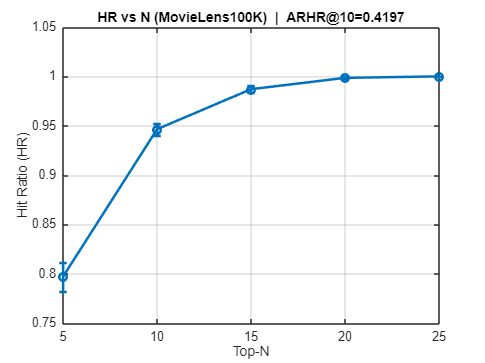

Saved report to: report_recom_mc_20251013_183518.txt




run_recom_mc_report(R)